## **Práctica 2: Análisis básico de voz y diseño de un vocoder LP**

### **Análisis básico de voz**

a.       Grabar una vocal y una consonante en sendos ficheros WAV. Representarlos e identificar sus frecuencias. Representar la energía de ambas señales usando espectrogramas.

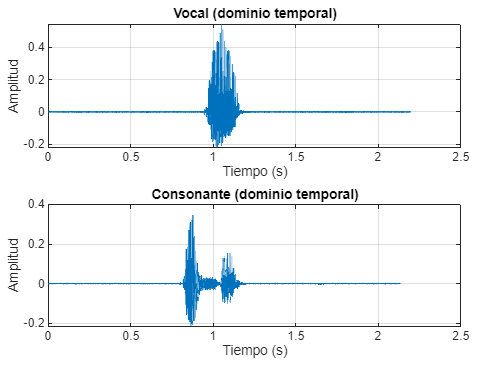

%% PRACTICA 2 — Apartado A
% Analisis basico de voz y diseno de un vocoder LP (A: inspeccion inicial)
% Archivos requeridos en el mismo directorio:
%   - vocal.wav          (una vocal sostenida, p.ej. /a/)
%   - consonante.wav     (una consonante, idealmente sorda, p.ej. /s/)
%
% Este script:
%  1) Carga y normaliza las señales.
%  2) Las representa en el dominio temporal.
%  3) Estima sus "frecuencias" características:
%       - Para la vocal: frecuencia fundamental F0 (pitch) por autocorrelación.
%       - Para la consonante (ruido): centroide espectral y banda dominante.
%  4) Muestra la energía usando espectrogramas (potencia en dB).
%
% Si quieres reproducir audio, descomenta las líneas con soundsc.

clear; clc; close all;

%% ---------- Utilidades de parámetros ----------
% Ventanas y hop para análisis de corto plazo
win_dur   = 0.040;   % 40 ms (bueno para voz)
hop_dur   = 0.010;   % 10 ms (solape 75%)
fft_len   = 2048;    % largo de FFT (suficientemente fino para voz)
f0_min    = 60;      % Hz, rango típico de voz humana
f0_max    = 400;     % Hz

%% ---------- Carga y preprocesado ----------
[v, Fs_v] = audioread('vocal.wav');         % vocal sostenida
[c, Fs_c] = audioread('consonante.wav');    % consonante (ruidosa)
v = mean(v,2); c = mean(c,2);               % por si son estéreo -> mono
v = v / max(1, max(abs(v)));                % normaliza sin dividir por 0
c = c / max(1, max(abs(c)));

% (Opcional) elimina offset DC para prevenir sesgos en autocorrelación
v = v - mean(v);
c = c - mean(c);

% soundsc(v,Fs_v); pause(length(v)/Fs_v + 0.2);
% soundsc(c,Fs_c);

%% ---------- Representación temporal ----------
t_v = (0:numel(v)-1)/Fs_v;
t_c = (0:numel(c)-1)/Fs_c;

figure('Name','Señales en el tiempo','Color','w');
tiledlayout(2,1,'Padding','compact','TileSpacing','compact');

nexttile;
plot(t_v, v, 'LineWidth', 1); grid on;
xlabel('Tiempo (s)'); ylabel('Amplitud');
title('Vocal (dominio temporal)');

nexttile;
plot(t_c, c, 'LineWidth', 1); grid on;
xlabel('Tiempo (s)'); ylabel('Amplitud');
title('Consonante (dominio temporal)');


%% ---------- Estimación de frecuencia fundamental (Vocal) ----------
% Pitch por autocorrelación sobre frames; se reporta la mediana de F0 válidos.
[F0_v, F0_track_v, tv_frames_v] = estimate_f0_autocorr(v, Fs_v, f0_min, f0_max, win_dur, hop_dur);

% Informe básico en consola
if ~isempty(F0_v) && ~isnan(F0_v)
    fprintf('F0 estimada (vocal): %.1f Hz\n', F0_v);
else
    fprintf('No se pudo estimar F0 confiable para la vocal.\n');
end

F0 estimada (vocal): 112.1 Hz


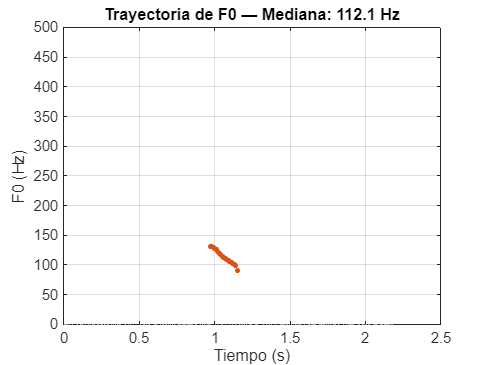


% Visualiza la trayectoria de F0 sobrepuesto al tiempo
figure('Name','Pitch vocal','Color','w');
plot(t_v, v*0.7, 'Color', [0.6 0.6 0.6]); hold on; % señal escalada solo como referencia visual
scatter(tv_frames_v, F0_track_v, 12, 'filled'); grid on;
ylim([0 max(500, f0_max+50)]);
xlabel('Tiempo (s)'); ylabel('F0 (Hz)');
title(sprintf('Trayectoria de F0 — Mediana: %.1f Hz', F0_v));

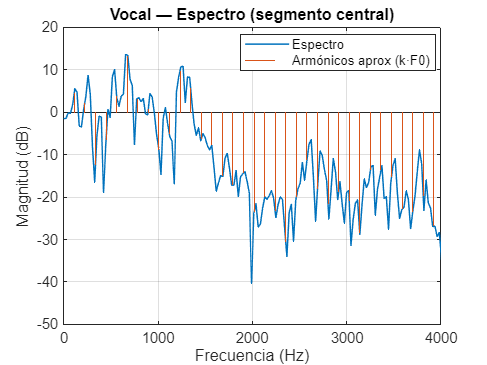


%% ---------- Espectro de potencia y picos (Vocal) ----------
% FFT del segmento central (para evitar ataques/colas)
seg_dur = 0.300; % 300 ms
[v_seg, f_v, Vdb] = middle_segment_spectrum(v, Fs_v, seg_dur, fft_len);

figure('Name','Espectro vocal','Color','w');
plot(f_v, Vdb, 'LineWidth',1); grid on;
xlim([0 4000]); xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dB)');
title('Vocal — Espectro (segmento central)');
% Marca armónicos aproximados usando F0
if ~isnan(F0_v) && F0_v>0
    hs = F0_v:F0_v:4000;
    yline_vals = interp1(f_v, Vdb, min(hs, f_v(end)), 'linear','extrap');
    hold on; stem(hs, yline_vals, 'filled', 'Marker','none');
    legend('Espectro','Armónicos aprox (k·F0)','Location','best');
end


%% ---------- Métricas espectrales para la consonante (ruidosa) ----------
% Para sonidos ruidosos no hay F0 clara. Usamos:
%  - Centroide espectral (media ponderada en frecuencia)
%  - Banda dominante (pico de la envolvente espectral)
[~, f_c, Cdb] = middle_segment_spectrum(c, Fs_c, seg_dur, fft_len);

% Centroide espectral
P = 10.^(Cdb/20);        % magnitud lineal (aprox) para ponderar
P = P.^2;                % potencia (mejor para centroides)
centroid_Hz = sum(f_c(:).*P(:)) / max(eps, sum(P));
% Pico dominante (frecuencia de potencia máxima)
[~, idx_pk] = max(P);
peak_Hz = f_c(idx_pk);

fprintf('Consonante — centroide espectral: %.0f Hz | pico dominante: %.0f Hz\n', centroid_Hz, peak_Hz);

Consonante — centroide espectral: 8601 Hz | pico dominante: 117 Hz


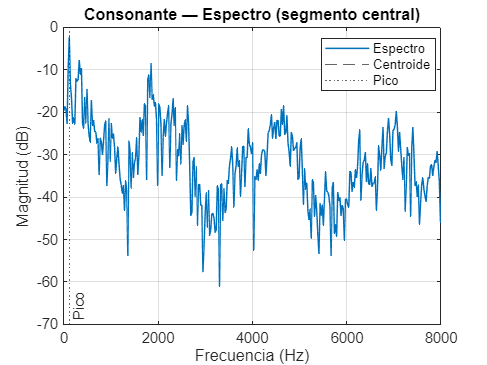


figure('Name','Espectro consonante','Color','w');
plot(f_c, Cdb, 'LineWidth',1); grid on;
xlim([0 8000]); xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dB)');
title('Consonante — Espectro (segmento central)');
hold on; xline(centroid_Hz, '--', 'Centroide', 'LabelVerticalAlignment','bottom');
xline(peak_Hz, ':', 'Pico', 'LabelVerticalAlignment','bottom');
legend('Espectro','Centroide','Pico','Location','best');

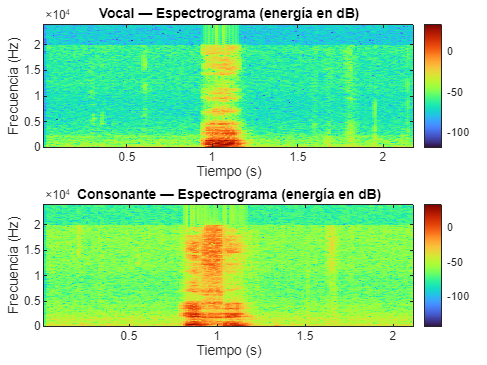


%% ---------- Espectrogramas (energía tiempo-frecuencia) ----------
% La energía se representa como potencia en dB dentro del espectrograma.
% Elegimos ventana Hamming y solape coherente con win/hop.
win_v  = hamming(round(win_dur*Fs_v), 'periodic');
hop_v  = round(hop_dur*Fs_v);
win_c  = hamming(round(win_dur*Fs_c), 'periodic');
hop_c  = round(hop_dur*Fs_c);

figure('Name','Espectrogramas (energía)','Color','w');
tiledlayout(2,1,'Padding','compact','TileSpacing','compact');

nexttile;
[s_v, fsv, tsv] = spectrogram(v, win_v, numel(win_v)-hop_v, fft_len, Fs_v, 'yaxis');
imagesc(tsv, fsv, 20*log10(abs(s_v)+eps)); axis xy; colormap turbo; colorbar;
ylabel('Frecuencia (Hz)'); xlabel('Tiempo (s)');
title('Vocal — Espectrograma (energía en dB)');

nexttile;
[s_c, fsc, tsc] = spectrogram(c, win_c, numel(win_c)-hop_c, fft_len, Fs_c, 'yaxis');
imagesc(tsc, fsc, 20*log10(abs(s_c)+eps)); axis xy; colormap turbo; colorbar;
ylabel('Frecuencia (Hz)'); xlabel('Tiempo (s)');
title('Consonante — Espectrograma (energía en dB)');


%% ---------- Helpers: funciones locales ----------
function [F0_median, F0_track, t_frames] = estimate_f0_autocorr(x, Fs, f0_min, f0_max, win_dur, hop_dur)
% Estima F0 por autocorrelación frame a frame y devuelve:
%   - F0_median: mediana de F0 válidos.
%   - F0_track:  vector con F0 por frame (NaN si no confiable).
%   - t_frames:  tiempo central de cada frame.
    x = x(:);
    Nw  = round(win_dur*Fs);
    Nh  = round(hop_dur*Fs);
    N   = numel(x);
    idx = 1;
    F0s = [];
    t_frames = [];
    while idx+Nw-1 <= N
        frame = x(idx:idx+Nw-1) .* hamming(Nw,'periodic');
        frame = frame - mean(frame);
        % Autocorrelación rápida vía FFT (opcional: xcorr)
        r = ifft( abs(fft(frame, 2^nextpow2(2*Nw))) .^2, 'symmetric' );
        r = r(1:Nw);                          % lags no negativos
        % Ignora muy pequeños
        r = r / max(eps, r(1));               % normaliza por r(0)
        % Buscar máximos en lags correspondientes al rango de F0
        lag_min = floor(Fs/f0_max);
        lag_max = ceil(Fs/f0_min);
        if lag_max > numel(r), lag_max = numel(r); end
        [pk, lag] = max(r(lag_min:lag_max));
        lag = lag + lag_min - 1;
        % Criterio de sonoridad: pico suficiente y energía del frame
        voiced = pk > 0.3 && rms(frame) > 0.01;
        if voiced
            F0 = Fs / lag;
        else
            F0 = NaN;
        end
        F0s(end+1,1) = F0; %#ok<AGROW>
        % Tiempo central del frame
        t_frames(end+1,1) = (idx + Nw/2 - 1) / Fs; %#ok<AGROW>
        idx = idx + Nh;
    end
    F0_track = F0s;
    F0_median = median(F0s(~isnan(F0s)));
    if isempty(F0_median), F0_median = NaN; end
end

function [xseg, f, Xdb] = middle_segment_spectrum(x, Fs, seg_dur, nfft)
% Devuelve espectro en dB de un segmento centrado (para evitar transitorios)
    x = x(:);
    N = numel(x);
    Ns = round(seg_dur*Fs);
    if Ns > N, Ns = N; end
    c0 = floor(N/2);
    i1 = max(1, c0 - floor(Ns/2));
    i2 = min(N, i1 + Ns - 1);
    xseg = x(i1:i2);
    xseg = xseg .* hamming(numel(xseg),'periodic');
    X = fft(xseg, nfft);
    X = X(1:floor(nfft/2)+1);
    f = linspace(0, Fs/2, numel(X)).';
    Xdb = 20*log10(abs(X) + eps);
end


Medidas complementarias

%% --- Medidas complementarias (robustas) ---
% Duración
dur_v = numel(v)/Fs_v;
dur_c = numel(c)/Fs_c;

% Energía RMS en dBFS (0 dBFS = señal a amplitud 1)
E_v_dBFS = 10*log10(mean(v.^2)+eps);
E_c_dBFS = 10*log10(mean(c.^2)+eps);

fprintf('Duración vocal: %.2f s | Energía: %.2f dBFS\n', dur_v, E_v_dBFS);

Duración vocal: 2.20 s | Energía: -30.77 dBFS


fprintf('Duración consonante: %.2f s | Energía: %.2f dBFS\n', dur_c, E_c_dBFS);

Duración consonante: 2.13 s | Energía: -34.26 dBFS



% ---------- Ancho de banda de la vocal sobre ENVOLVENTE (no armónicos) ----------
% Usa el mismo segmento y FFT que ya calculaste para la vocal:
% [v_seg, f_v, Vdb] = middle_segment_spectrum(v, Fs_v, seg_dur, fft_len);

P  = (10.^(Vdb/20)).^2;                  % potencia lineal
df = f_v(2)-f_v(1);
winHz = 200;                              % anchura de suavizado (150–300 Hz va bien)
winN  = max(3, round(winHz/df));
Penv  = movmean(P, winN);                 % envolvente suavizada
PenvdB = 10*log10(Penv+eps);

% Encuentra pico de la envolvente (F1 aprox) y ancho de banda a -3 dB
[pk, idx_pk_env] = max(PenvdB);
lev = pk - 3;                             % nivel -3 dB
iL = find(PenvdB(1:idx_pk_env) <= lev, 1, 'last');
iR = idx_pk_env - 1 + find(PenvdB(idx_pk_env:end) <= lev, 1);

if ~isempty(iL) && ~isempty(iR)
    BW_Hz = f_v(iR) - f_v(iL);
    F1_Hz = f_v(idx_pk_env);
else
    % Si no hay cruces, amplía suavizado y reintenta o deja NaN
    BW_Hz = NaN; F1_Hz = f_v(idx_pk_env);
end
fprintf('Vocal: pico envolvente ~F1 = %.0f Hz | Ancho de banda (-3 dB) = %s\n', ...
        F1_Hz, string(round(BW_Hz)));

Vocal: pico envolvente ~F1 = 609 Hz | Ancho de banda (-3 dB) = 258



% ---------- Alternativa: Formantes con LPC (opcional, añade al informe) ----------
% p = 12; a = lpc(v, p); r = roots(a); r = r(imag(r)>=0);
% F = atan2(imag(r),real(r))*Fs_v/(2*pi); B = -(Fs_v/pi)*log(abs(r));
% mask = F>90 & F<4000; F=F(mask); B=B(mask); [F,ix]=sort(F); B=B(ix);
% if numel(F)>=2
%     fprintf('LPC: F1=%.0f Hz (BW=%.0f Hz), F2=%.0f Hz (BW=%.0f Hz)\n', F(1),B(1),F(2),B(2));
% end

% ---------- Centroide espectral (útil para comparar con consonante) ----------
% Para vocal (mismo segmento):
centroid_v = sum(f_v(:).*P(:))/max(eps, sum(P));
% Para consonante, reutiliza su espectro central (Cdb y f_c de tu script)
Pc = (10.^(Cdb/20)).^2;
centroid_c = sum(f_c(:).*Pc(:))/max(eps, sum(Pc));
fprintf('Centroide vocal: %.0f Hz | Centroide consonante: %.0f Hz\n', centroid_v, centroid_c);

Centroide vocal: 827 Hz | Centroide consonante: 8601 Hz



% ---------- (Opcional) Mini tabla en consola ----------
fprintf('\nResumen:\n');


Resumen:


fprintf('%-14s %-8s %-10s %-12s %-12s\n','Señal','Dur(s)','E(dBFS)','Centroid(Hz)','BW(-3dB)');

Señal          Dur(s)   E(dBFS)    Centroid(Hz) BW(-3dB)    


fprintf('%-14s %-8.2f %-10.2f %-12.0f %-12s\n','Vocal',dur_v,E_v_dBFS,centroid_v, string(round(BW_Hz)));

Vocal          2.20     -30.77     827          258         


fprintf('%-14s %-8.2f %-10.2f %-12.0f %-12s\n','Consonante',dur_c,E_c_dBFS,centroid_c,'—');

Consonante     2.13     -34.26     8601         —           


b.      Grabar una frase corta en un fichero WAV y hacer un análisis de la misma tanto en el dominio temporal como en el de la frecuencia con un espectrograma.

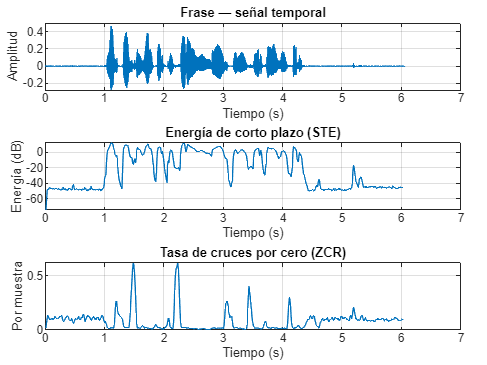

%% --------------------------------------------------------------
% PRACTICA 2 — Apartado B
% Análisis de una frase (frase.wav)
% --------------------------------------------------------------

% Usa la misma función estimate_f0_autocorr definida previamente (en el A)

clearvars -except estimate_f0_autocorr;  % conserva la función del A
clc; close all;

%% ---------- Parámetros ----------
win_dur   = 0.030;   % 30 ms
hop_dur   = 0.010;   % 10 ms
fft_len   = 2048;
f0_min    = 60;
f0_max    = 400;

%% ---------- Carga de la frase ----------
[x, Fs] = audioread('frase.wav');
x = mean(x,2);
x = x / max(1, max(abs(x)));
x = x - mean(x);
t = (0:numel(x)-1)/Fs;

% soundsc(x,Fs);   % opcional

%% ---------- Energía y cruces por cero ----------
Nw  = round(win_dur*Fs);
Nh  = round(hop_dur*Fs);
win = hamming(Nw,'periodic');

num_frames = 1 + floor((numel(x)-Nw)/Nh);
STE = zeros(num_frames,1);
ZCR = zeros(num_frames,1);
t_frames = zeros(num_frames,1);

for n = 1:num_frames
    i1 = (n-1)*Nh + 1;
    seg = x(i1:i1+Nw-1) .* win;
    STE(n) = sum(seg.^2);
    sgn = sign(seg); sgn(sgn==0)=1;
    ZCR(n) = sum(abs(diff(sgn)))/2 / numel(seg);
    t_frames(n) = (i1 + Nw/2 - 1)/Fs;
end
STE_dB = 10*log10(STE + eps);

%% ---------- Representaciones temporales ----------
figure('Name','Análisis temporal - Frase','Color','w');
tiledlayout(3,1,'Padding','compact','TileSpacing','compact');

nexttile;
plot(t,x); grid on; title('Frase — señal temporal');
xlabel('Tiempo (s)'); ylabel('Amplitud');

nexttile;
plot(t_frames, STE_dB); grid on;
title('Energía de corto plazo (STE)');
xlabel('Tiempo (s)'); ylabel('Energía (dB)');

nexttile;
plot(t_frames, ZCR); grid on;
title('Tasa de cruces por cero (ZCR)');
xlabel('Tiempo (s)'); ylabel('Por muestra');

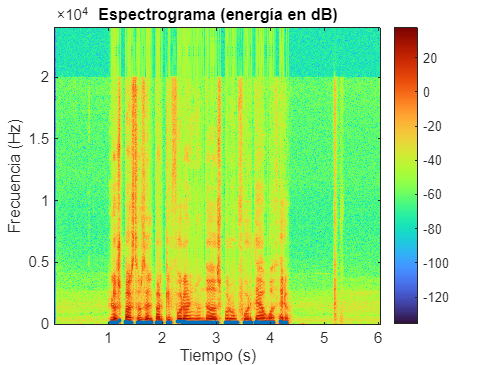


%% ---------- Espectrograma ----------
win_sp = hamming(Nw,'periodic');
overl  = Nw - Nh;

figure('Name','Espectrograma - Frase','Color','w');
[s,f,ts] = spectrogram(x, win_sp, overl, fft_len, Fs, 'yaxis');
imagesc(ts, f, 20*log10(abs(s)+eps)); axis xy; colormap turbo; colorbar;
xlabel('Tiempo (s)'); ylabel('Frecuencia (Hz)');
title('Espectrograma (energía en dB)');

%% ---------- Trayectoria de F0 ----------
[F0_med, F0_track, tF0] = estimate_f0_autocorr(x, Fs, f0_min, f0_max, win_dur, hop_dur);
hold on;
mask = ~isnan(F0_track) & F0_track>0;
plot(tF0(mask), F0_track(mask), '.', 'MarkerSize',8);

% legend('Energía (dB)','Pitch (F0)','Location','southoutside');
fprintf('F0 mediana estimada: %.1f Hz\n', F0_med);

F0 mediana estimada: 119.7 Hz
